srcDir = "..\srcImages\";
building_dark = readraw(srcDir + "building.raw");

    "→Retrieving Image "    "..\srcImages\building.raw"    " ..."



building_noise = readraw(srcDir + "building_noise.raw");

    "→Retrieving Image "    "..\srcImages\building_noise.raw"    " ..."



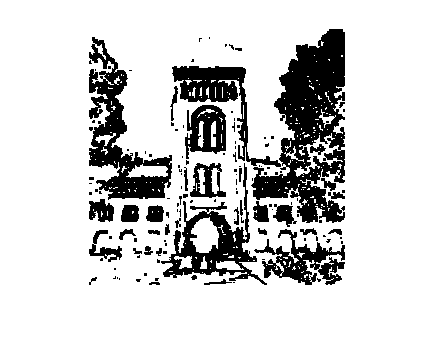


%edgeMap = sobelEdgeMap(building_dark, @sobel3x3Horizontal, @sobel3x3Vertical, 0.15);
%imshow(edgeMap);

edgeMap = laplaceEdgeMap(building_dark, 0.2);
imshow(edgeMap);

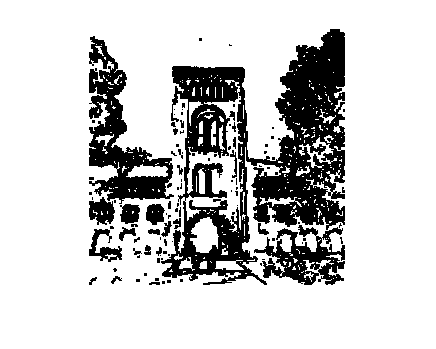


%edgeMap = sobelEdgeMap(building_noise, @sobel3x3Horizontal, @sobel3x3Vertical, 0.4);
%imshow(edgeMap);

%edgeMap = sobelEdgeMap(building_noise, @sobel7x7Horizontal, @sobel7x7Vertical, 0.2);
%imshow(edgeMap);

%edgeMap = laplaceEdgeMap(building_noise, 0.4);
%imshow(edgeMap);

building_contrast = contrastHistogramEqualized(building_dark);
%imshow(building_contrast);

%edgeMap = sobelEdgeMap(building_contrast, @sobel3x3Horizontal, @sobel3x3Vertical, 0.2);
%imshow(edgeMap);

edgeMap = laplaceEdgeMap(building_contrast, 0.25);
imshow(edgeMap);


%building_blur = applyMedianFilter(building_noise, 5);
%imshow(building_blur);

%edgeMap = sobelEdgeMap(building_blur, @sobel3x3Horizontal, @sobel3x3Vertical, 0.2);
%imshow(edgeMap);

%edgeMap = laplaceEdgeMap(building_blur, 0.2);
%imshow(edgeMap);

srcDir = "..\srcImages\";
patterns = readraw(srcDir + "patterns.raw");

    "→Retrieving Image "    "..\srcImages\patterns.raw"    " ..."



pcb = readraw(srcDir + "pcb.raw");

    "→Retrieving Image "    "..\srcImages\pcb.raw"    " ..."




shrinkConditional = toLookupTable(Constants.SHRINK_CONDITIONAL);
shrinkInhibitor = toLookupTable(Constants.SHRINK_UNCONDITIONAL);

thinConditional = toLookupTable(Constants.THIN_CONDITIONAL);
thinInhibitor = toLookupTable(Constants.THIN_UNCONDITIONAL);

skeletonizeConditional = toLookupTable(Constants.SKELETONIZE_CONDITIONAL);
skeletonizeInhibitor = toLookupTable(Constants.SKELETONIZE_UNCONDITIONAL);

test = [255	255	255	255	255	0	255	255	255	255	255	255	255	255	255	255;
255	255	255	255	255	0	255	255	255	255	255	255	255	255	255	255;
255	255	255	255	255	0	255	255	255	255	255	255	255	255	255	255;
255	255	255	255	255	0	255	255	255	255	255	255	255	255	255	255;
255	255	255	0	0	0	0	255	255	0	0	0	0	0	0	255;
255	255	255	0	0	0	0	0	0	0	0	0	0	0	255	255;
255	255	255	0	0	0	0	0	0	0	0	0	0	255	255	255;
255	255	255	0	0	0	0	0	0	0	0	0	255	255	255	255;
255	255	255	0	0	0	0	0	0	0	0	0	255	255	255	255;
255	255	255	0	0	0	0	0	0	0	0	255	255	255	255	255;
255	255	255	0	0	0	0	0	0	0	255	255	255	255	255	255;
255	255	255	0	0	0	0	0	0	255	255	255	255	255	255	255;
255	255	255	0	0	0	0	0	255	255	255	255	255	255	255	255;
255	255	255	0	0	0	0	0	255	255	255	255	255	255	255	255;
255	255	255	255	0	0	0	255	255	255	255	255	255	255	255	255;
255	255	255	255	0	0	255	255	255	255	255	255	255	255	255	255;
255	255	255	255	0	255	255	255	255	255	255	255	255	255	255	255;
255	255	255	255	255	255	255	255	255	255	255	255	255	255	255	255;];
%disp(test);
shrinkPattern = morphologicalProcess(test, shrinkConditional, shrinkInhibitor);
disp(shrinkPattern);

   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255
   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255
   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255
   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255
   255   255   255   255   255   255   255   255   255   255   255   255   255     0   255   255
   255   255   255   255   255   255   255   255   255   255   255     0     0     0   255   255
   255   255   255   255   255   255   255   255   255     0     0   255   255   255   255   255
   255   255   255   255   255   255   255   255   255     0   255   255   255   255   255   255
   255   255   255   255   255   255     0     0     0   255   255   255   255   255   255   255
   255   255   255   255   255   255     0   255   255   255   255   255   255   255   255   255
   255   255   255   255   255


star = patterns(145:240, 145:225);
binary = toBinary(star);
%disp(binary);
[width, height] = size(binary);

outImg = binary;
shouldContinue = false;
while shouldContinue
    shouldContinue = false;
    marked = zeros(width, height);
    for x = 1:width
        for y = 1:height
            if hitOrMiss(outImg, x, y, shrinkConditional)
                marked(y, x) = 1;
            else
                marked(y, x) = 0;
            end
            %if x == 5 && y == 3
            %    hitOrMiss(outImg, x, y, conditionalLookup);
            %    stackPx(outImg, x, y);
            %end
        end
    end
    %disp(uint8(marked));
    for x = 1:width
        for y = 1:height
            if marked(y, x) == 1 && ~hitOrMiss(marked, x, y, shrinkInhibitor)
                outImg(y, x) = 0;
                shouldContinue = true;
            end
        end
    end
    %disp(outImg);
    
    current = fromBinary(outImg);
    figure;
    imshow(current);
    drawnow;
end

%imshow(patterns);
%shrinkPattern = morphologicalProcess(patterns, shrinkConditional, shrinkInhibitor);
%imshow(shrinkPattern);

%thinPattern = morphologicalProcess(patterns, thinConditional, thinInhibitor);
%imshow(thinPattern);

%skeletonPattern = morphologicalProcess(patterns, skeletonizeConditional, skeletonizeInhibitor);
%imshow(skeletonPattern);

%imshow(pcb);
%shrinkPattern = morphologicalProcess(pcb, shrinkConditional, shrinkInhibitor);
%imshow(shrinkPattern);

%thinPattern = morphologicalProcess(pcb, thinConditional, thinInhibitor);
%imshow(thinPattern);

%skeletonPattern = morphologicalProcess(pcb, skeletonizeConditional, skeletonizeInhibitor);
%imshow(skeletonPattern);

